# V768 - Measuring Vision with Psychophysics

## Lab 3 - Forced Choice Experiments

In Lab 1, you measured signal detection performance using the method of constant stimuli. Each trial required you to answer the question "Did you see a stimulus?". This was a yes-no task, also sometimes called a **simple forced choice** experiment.

In this lab, you will measure signal detection performance using a **two-alternative forced choice (2AFC)** experiment. Each trial will require you to answer the question "Did you see a stimulus on the left or the right of the screen?", even if you did not see a stimulus on either side.

This lab will show you how to fit a **psychometric function** to the resulting data. How similar or different will those curves be? What about them will be similar or different? Let's find out!

### Learning Outcomes

(i.e., what you will be able to do at the end of this lab)

- Describe simple forced choice and two-alternative forced choice experiments. Identify similarites and differences.

- Describe a psychometric curve.

- For a psychometric function with parameters mu, sigma, guess rate, and lapse rate, explain the signficance of each parameter.

- Explain why some psychometric curves have a floor of 0% and others have a floor of 50%.

### Questions

- Include and write a caption for the figure in Part C, Step 1.

- Include and write a caption for the table in Part C, Step 2.

- List the parameters of the psychometric function used for this lab. Describe the signficance of each, including the impact that changing its value will have on the resulting curve.

- Describe simple forced choice and two-alternative forced choice experiments, and discuss their similarities and differences.

- Reflect on what you know about these two experiment types and what you have observed. Do you think both are measuring the same thing? Do you expect that their results are usually similar or different? Do you think that one is likely more reliable than the other? Explain your reasoning.

## A. Method of Constant Stimuli

### Step 1. Data collection

In the first lab, you collected data using the PsychoPy experiment file "method-of-constant-stimuli.psyexp", so you've already completed data collection for this part of the lab!

### Step 2. Load your data

*(Reminder: PsychoPy will save your experiment data to a "data" folder inside of the same folder as the ".psyexp" file. The filename will start with the subject ID you used and end with the date/time of data collection.)*

Find the name of the ".csv" file containing your experiment data, and enter it below. Then run this section of code.

% change the filename to the one you generated during data collection
detection_file = fullfile("..", "01-classical-methods", "method-of-constant-stimuli", "data", ...
    "demo_method_of_constant_stimuli_2025-01-16_21h16.39.043.csv");

% load the data table
warning off;
detection_data = readtable(detection_file);
warning on;

% remove the rows/columns associated with the instructions in psychopy
detection_data(1,:)=[];
remove = {'notes','begin_experiment_started','begin_experiment_stopped'};
detection_data(:,remove) = [];

### Step 3. Analyze your data

For this experiment, PsychoPy saved the stimulus contrast and the participant's response per trial. The responses were stored as 'up' (stimulus present) or 'down' (stimulus not present).

% convert the response key to true for up and false for down
detection_data.response = strcmp(detection_data.response_keys,'up');

#### Find percentage of stimuli reported present (up), as a function of contrast

For each contrast level, how often did you report that a stimulus was present?

% average across responses per contrast level
analysis_table = table(detection_data.response, detection_data.contrast, ...
    'VariableNames',["response","contrast"]);
detection_results = grpstats(analysis_table,'contrast');

% display percentages
percent_detected = table(detection_results.contrast, detection_results.mean_response*100, ...
    'VariableNames',["contrast", "reported present (%)"]);
disp(percent_detected)

    contrast    reported present (%)
    ________    ____________________

          0                30       
      1e-05            26.667       
     0.0001            23.333       
      0.001                40       
       0.01            96.667       
        0.1               100       
        0.9               100       



**Take a look at these percentages.** What is the maximum? What is the minimum?

**Think about the design of this experiment.** (What did the stimuli look like? What was the task? What were the potential responses? etc.). What results would you get if you were performing at chance level? In other words, what would happen if you just guessed on every trial?

**Looking again at your results,** when did you perform at chance level? Above chance? Below chance? What does that say about what contrast levels you can and cannot see?

#### Plot responses as a function of contrast

Let's plot those percentages and take a look at the curve they form.

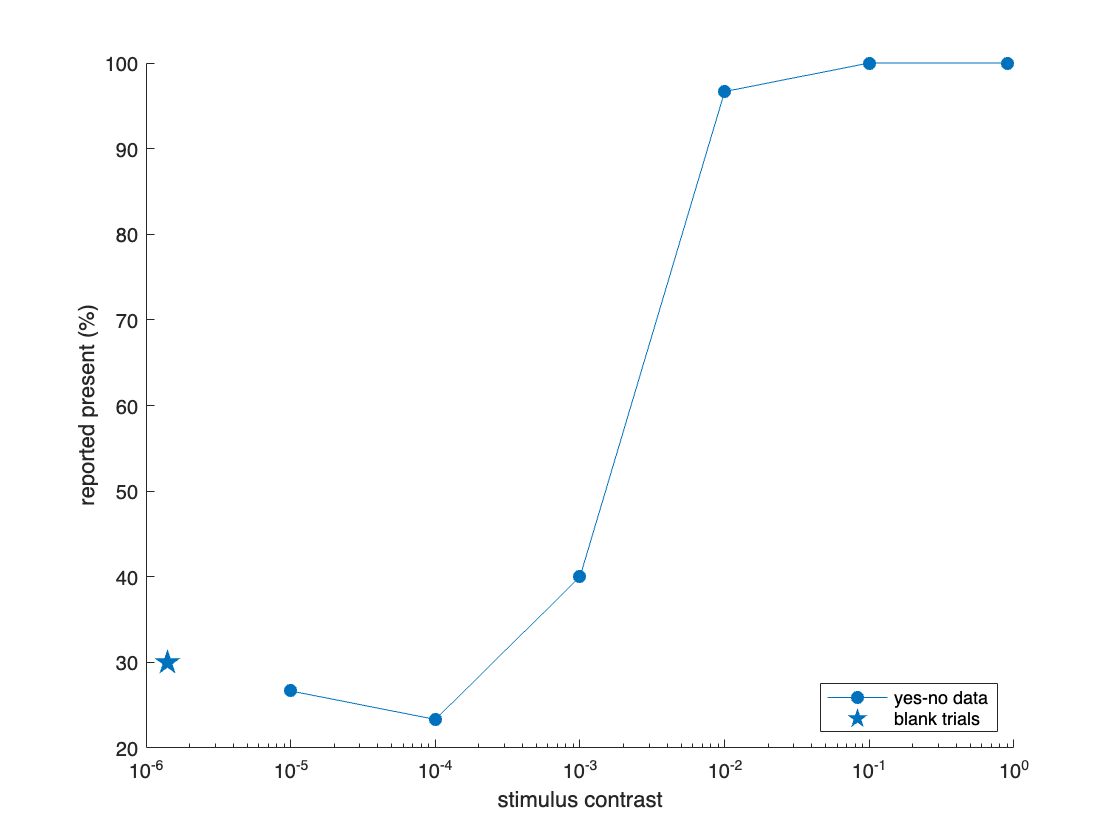

figure; hold on;

% stash RGB values for default MATLAB colors
% (blue, orange, gold, purple, green, sky blue, red)
rgb_matlab = [0, 0.447, 0.741; 0.85, 0.325, 0.098; 0.929, 0.694, 0.125; ...
    0.494, 0.184, 0.556; 0.466, 0.674, 0.188; 0.301, 0.745, 0.933; 0.635, 0.078, 0.184];

% plot with stimulus contrast on a log scale
% (trials with zero contrast will not be included)
plot(detection_results.contrast, detection_results.mean_response*100, ...
    'o-', 'Color',rgb_matlab(1,:), 'MarkerFaceColor',rgb_matlab(1,:))
set(gca,'XScale','log')
xlabel('stimulus contrast')
ylabel('reported present (%)')

% add a dot for zero contrast (blank) trials
x_val_for_detection_blanks = ...  % pick dummy value for plotting zero contrast results
    detection_results.contrast(2)/10 + ...  % move a 10^-1 step below the smallest value
    detection_results.contrast(2)/25;  % shift slightly to the right (off the y-axis line)
plot(x_val_for_detection_blanks, detection_results.mean_response(1)*100, ...
    'pentagram', 'MarkerSize',12, 'Color',rgb_matlab(1,:), 'MarkerFaceColor',rgb_matlab(1,:))
legend(["yes-no data","blank trials"], 'Location','southeast')

drawnow

**Looking at this curve,** does the shape remind you of anything? Perhaps a sigmoid? A cumulative density function (CDF)? A psychometric function?

### Step 4. Fit a psychometric curve to your data

**Psychometrics** is a field of study that aims to objectively measure variables that cannot be directly observed (e.g., a person's absolute contrast threshold). A **psychometric function** models the relationship between a given stimulus feature (e.g., contrast) and a participant's forced-choice responses. After we fit a psychometric function to data from a detection or discrimination task, we can infer certain things about that stimulus-response relationship (i.e., a psychometric function is an ***inferential model***).

#### What is the equation of a psychometric function?

There isn't one "true" equation for psychometric functions. You might come across a variety of different equations in textbooks and journal articles.

For this lab, we'll use an equation that builds on the normal cumulative density function (CDF). A Gaussian CDF has two parameters: the **mean** (mu, $\mu$) and the **standard deviation** (sigma, $\sigma$).

The y-axis values of a CDF can range from 0 to 1 (0% to 100%). You may notice, however, that psychometric curves don't always reach 0 or 1. For example, let's say that performance on a certain task only falls between 30% and 90%. What can we add to our equation to account for that?

A **guess rate** (gamma, $\gamma$) will to adjust the function's minimum value, and a** lapse rate** (lambda, $\lambda$) will adjust the function's maximum value. Both values convey the ***magnitude*** of the adjustment. For example, a guess rate of 30% would shift the function's minimum value from 0% to 30%, and a lapse rate of 10% would shift the function's maximum value from 100% to 90%.

**How do we incorporate the guess and lapse rates into our equation?** Let's say we want to change the bounds of our curve from 0 and 1 to 0.3 to 0.9 (30% to 90%). As we just covered, that means implementing a guess rate of 0.3 and a lapse rate of 0.1. Both of these rates reduce our function's height (meaning, how much of the y-axis that it can traverse). Thus, subtracting those rates from the maximum value of a CDF (1; 100%) gives us the height that we want our curve to have: $1-0\ldotp 3-0\ldotp 1=0\ldotp 6$. We can adjust our curve's height by scaling our CDF by the height we want (i.e., by multiplying the CDF by 0.6; 100% will become 60%, 50% will become 30%, etc.). After scaling, our curve will range from 0 to 0.6, which is 0.3 from where we want it to be. Thus, the second (and last) thing that we need to do is shift our curve up by our desired minimum value, which is equal to our guess rate, 0.3. (*Note: This isn't essential to understand, but at least give it a try to help grow your ability to make sense of equations.*)

The **equation** that we end up with for our **psychometric function **$\psi$ is


$$\mathbf{p}=\psi \left(\mathbf{x};\mu ,\sigma ,\gamma ,\lambda \right)=\textrm{CDF}\left(\mathbf{x};\mu ,\sigma \right)\cdot \left(1-\gamma -\lambda \right)+\gamma$$


where $\mathbf{x}$ represents the levels of the stimulus feature of interest (contrast) and $\mathbf{p}$ represents the corresponding response probabilities. The vector (i.e., set of values) $\mathbf{x}$ is the input to the functions $\psi$ and $\textrm{CDF}$, and the variables after the semicolon are that function's parameters.

#### Set up for curve fitting

To fit the function we just defined to data, we need to pick a guess for each of our parameter values ($\mu ,\sigma ,\gamma ,\lambda$). This will be the first combination of values that MATLAB tests. To perform fitting, MATLAB will (1) find the curve produced by our function $\psi$, our stimulus levels $\mathbf{x}$, and the set of parameter values; (2) compare that curve to the data; and (3) keep changing the parameter values until it finds a curve that's ***optimally*** close to the data (i.e., as close as MATLAB thinks it can find). This process is called **optimization**.

Keep in mind that, even with identical input values, optimization won't always produce the same result and that sometimes it requires quite a bit of fine-tuning.

One way to fine-tune an optimization procedure is to place bounds on your parameters, restricting the values they can have. In this case, our sigma, guess rate, and lapse rate values should not be negative, so we'll implement lower bounds of 0 for those parameters. (And we'll also ask MATLAB not to display any output to give us less to scroll through.)

% define psychometric function to fit
psyfxn = @(c,x) (normcdf(x, c(1), c(2)) * (1 - c(3) - c(4))) + c(3);
% c(1) = mu
% c(2) = sigma
% c(3) = guess rate
% c(4) = lapse rate

% choose starting values
c0 = [0, 1, 0, 0];

% choose lower bounds
c_low_b = [-Inf, 0, 0, 0];

% suppress lsqcurvefit auto-printing
% (e.g., "Local minimum found. Optimization completed because the size of
% the gradient is less than the value of the optimality tolerance.
% <stopping criteria details>")
opts = optimset('Display','off');

#### Fit your data

Now that we've chosen our function, initial guesses, and optional settings, we're ready to try fitting data from our yes-no task!

Note that we've been plotting our contrast levels on a logarithmic scale. (Since $\log_{10} {\textrm{10}}^x =x$, you can think of plotting on a log scale as treating ${\textrm{10}}^{-3}$, ${\textrm{10}}^{-2}$, and ${\textrm{10}}^{-1}$ like they were $-3$, $-2$, and $-1$.) Because contrast is better represented by a log scale (vs. a linear scale), we're going to fit the $\log_{10}$ of our contrast values. Thus, our mu and sigma values will be on a log scale as well (i.e., if MATLAB outputs a mu of $-3$, that means mu is ${\textrm{10}}^{-3}$).

% fit function to data
[psyfit_detection, resnorm_detection] = lsqcurvefit(psyfxn, c0, ...
    log10(detection_results.contrast), ...  % x values of psychometric curve
    detection_results.mean_response, ...  % y values of psychometric curve
    c_low_b, ...  % lower bounds on parameters
    [], opts);

% display results
fprintf(['        mu = %.4f\n', '     sigma = %.4f\n', ...
    'guess rate = %.4f\n', 'lapse rate = %.4f\n', ...
    '\n   resnorm = %.4f\n'], ...
    psyfit_detection(1), psyfit_detection(2), ...
    psyfit_detection(3), psyfit_detection(4), resnorm_detection)

        mu = -2.6517
     sigma = 0.3831
guess rate = 0.2667
lapse rate = 0.0004

   resnorm = 0.0022


Displayed above are the 4 "optimal" parameter values and an error metric. Specifically, MATLAB returned the **squared norm of the residual** (`resnorm`). This value is calculated by (1) finding the difference between your actual data points and the values of the fitted psychometric curve at the same contrast levels; (2) squaring each difference; and (3) summing the squared differences. A low `resnorm` is a good sign, but comparing a plot of your data and the fitted curve will give you an even better idea of how well MATLAB fit your data.

#### Create a curve to plot

To plot your psychometric curve, you'll first need a series of x-values, and you'll then need to evaluate your fitted psychometric curve at those x-values. The more values you include, the smoother the curve will be. Ideally, the curve will be smooth enough that you can see it's shape (vs. just a rough sketch). A set of 100 should be enough here.

% pick x values (evenly spaced along log axis & wider than data)
min_x = floor(log10(detection_results.contrast(2)/3)*10)/10;  % start a bit below lowest contrast
max_x = ceil(log10(detection_results.contrast(end)));  % end a bit above highest contrast
psy_x_detection = logspace(min_x, max_x, 100).';

% use psychometric curve function to calculate y values
psy_y_detection = psyfxn(psyfit_detection, log10(psy_x_detection));

#### Plot fitted psychometric curve

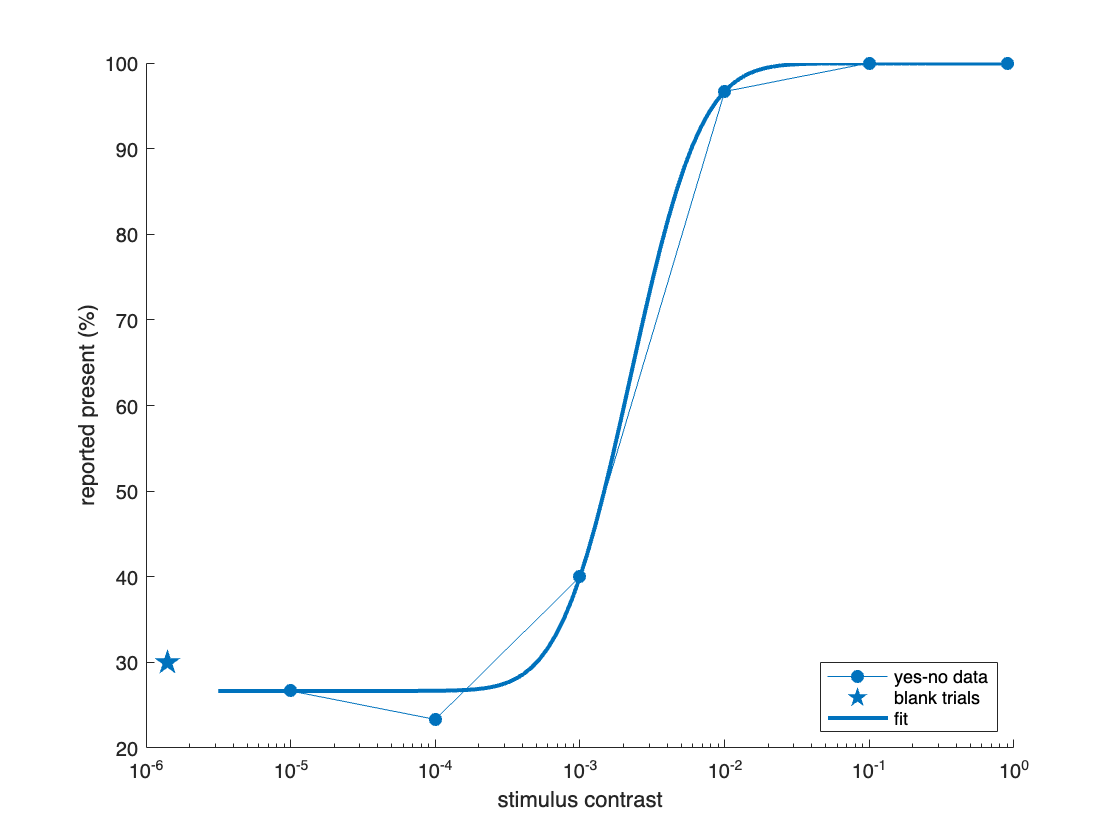

% plot signal detection results
figure; hold on;
plot(detection_results.contrast, detection_results.mean_response*100, ...
    'o-', 'Color',rgb_matlab(1,:), 'MarkerFaceColor',rgb_matlab(1,:))
plot(x_val_for_detection_blanks, detection_results.mean_response(1)*100, ...
    'pentagram', 'MarkerSize',12, 'Color',rgb_matlab(1,:), 'MarkerFaceColor',rgb_matlab(1,:))
set(gca,'XScale','log')
xlabel('stimulus contrast')
ylabel('reported present (%)')

% add fitted curve
plot(psy_x_detection, psy_y_detection*100, '-', 'Color',rgb_matlab(1,:), 'LineWidth',2)
legend(["yes-no data","blank trials","fit"], 'Location','southeast')

drawnow

**What do you think?** Did the optimization procedure do a good job fitting your data? Are some adjustments needed?

## Part B. Two-Alternative Forced Choice (2AFC)

### Step 1. Data collection

To collect data, open the PsychoPy ".psyexp" file in the folder titled "forced-choice", and run that experiment. The instructions will appear on the screen before the trials begin. The experiment includes 240 trials.

### Step 2. Load your data

PsychoPy will save your experiment data to a "data" folder (inside of the same folder as the ".psyexp" file). The filename will start with the subject ID you used and end with the date/time of data collection.

Find the name of the ".csv" file containing your experiment data, and enter it below. Then run this section of code.

Before running this section of code, find the name of the ".csv" file containing your experiment data, and enter it below.

% change the filename to the one you generated during data collection
choice_file = fullfile("forced-choice", "data", ...
    "demo_forced_choice_2025-01-28_22h20.20.760.csv");

% load the data table
warning off;
choice_data = readtable(choice_file);
warning on;

% remove the rows/columns associated with the instructions in psychopy
choice_data(1,:)=[];
remove = {'notes','begin_experiment_started','begin_experiment_stopped'};
choice_data(:,remove) = [];

### Step 3. Analyze your data

For this experiment, the stimulus was a sinusoidal grating with a Gaussian mask. As a reminder, the grayscale luminance range in PsychoPy is -1 to 1, where -1 is black, 1 is white, and 0 is middle gray. The background luminance was set to 0. Thus, if the stimulus contrast were 0, the grating would be middle gray (the same luminance as the background), and if the stimulus contrast were 1, the grating's luminance would range from black to white.

PsychoPy saved the stimulus contrast, stimulus location (1 = right; -1 = left), and the participant's response per trial. The responses were stored as 'left' or 'right'.

n_trials = size(choice_data,1);
trials = 1:n_trials;

% extract the stimulus's contrast level and location
stim_contrast = choice_data.contrast;
stim_location = choice_data.location;

% extract the response data
resp_key = choice_data.response_keys;

% convert the response key to 1 for right and -1 for left
% (to match stimulus location)
resp_location = double(strcmp(resp_key,'right'));
resp_location(resp_location==0) = -1;

#### Visualize the response per trial

Let's start by taking a look at the data for each trial. Plot the contrast level (dots) and an indicator of the participant's response (circles), with the color of each differentiating between left (blue) and right (orange).

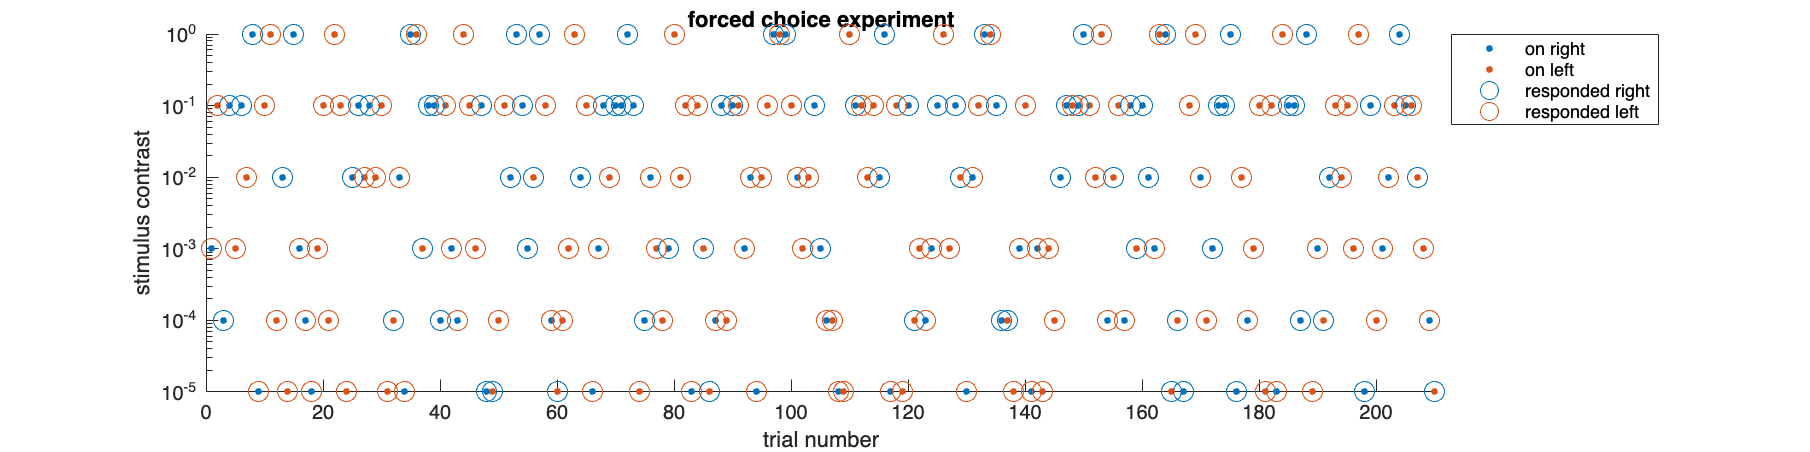

figure

% first, plot the stimulus contrast on a log scale
% (trials with zero contrast will not be included)
hold on;
plot(trials(stim_location==1), stim_contrast(stim_location==1), ...
    '.', 'MarkerSize',10);  % stimuli on the right
plot(trials(stim_location==-1), stim_contrast(stim_location==-1), ...
    '.', 'MarkerSize',10);  % stimuli on the left
set(gca,'YScale','log')
xlabel('trial number'); xlim([0,n_trials])
ylabel('stimulus contrast')
title('forced choice experiment')

% add circles indicating the participant's response
plot(trials(resp_location==1), stim_contrast(resp_location==1), ...
    'o', 'MarkerSize',10, 'Color',rgb_matlab(1,:));  % responsed on the right
plot(trials(resp_location==-1), stim_contrast(resp_location==-1), ...
    'o', 'MarkerSize',10, 'Color',rgb_matlab(2,:));  % responded on the left
legend({'on right', 'on left', 'responded right', 'responded left'},"Location","bestoutside")
set(gcf,'Position',[0,0,1000,250])

drawnow

#### Determine whether responses were correct or incorrect

For a responses to be correct, the location of the stimulus and the location that the participant reported must match (i.e., both "left" or both "right").

% do stimulus and response locations match?
resp_correct = stim_location == resp_location;

% display results
fprintf('Overall percentage correct = %.2f%%\n', mean(resp_correct)*100);

Overall percentage correct = 73.33%


#### Determine percentage correct per contrast level

For each contrast level, how often did you choose the correct side of the screen?

% average across responses per contrast level
analysis_table = table(resp_correct, stim_contrast, ...
    'VariableNames',["response","contrast"]);
choice_results = grpstats(analysis_table,'contrast');

% display percentages
percent_correct = table(choice_results.contrast, choice_results.mean_response*100, ...
    'VariableNames',["contrast", "correct responses (%)"]);
disp(percent_correct)

    contrast    correct responses (%)
    ________    _____________________

      1e-05            46.667        
     0.0001                50        
      0.001            53.333        
       0.01            63.333        
        0.1               100        
          1               100        



**Take a look at these percentages.** What is the maximum? What is the minimum?

**Think about the design of this experiment.** (What did the stimuli look like? What was the task? What were the potential responses? etc.). What results would you get if you were performing at chance level?

**Looking again at your results,** when did you perform at chance level? Above chance? Below chance? What does that say about what contrast levels you can and cannot see?

#### Plot percentage correct as a function of contrast

Let's plot these percentages and check out the curve they form.

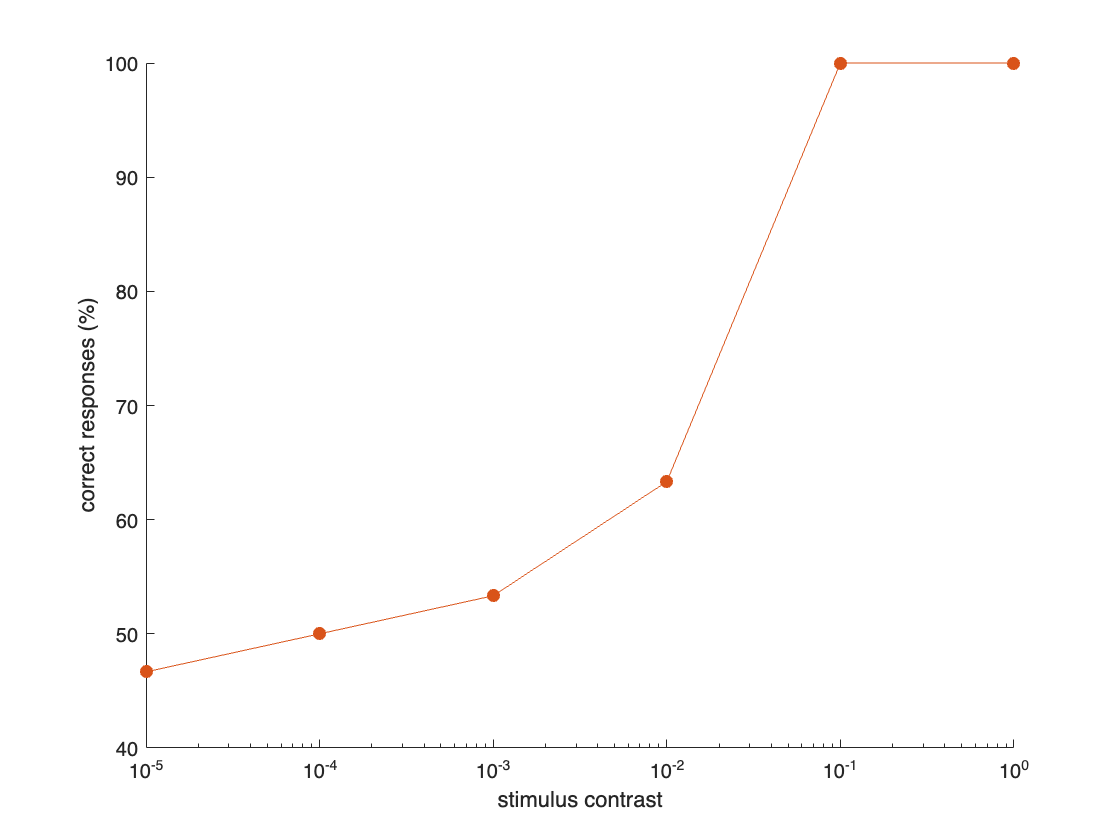

figure; hold on;

% plot with stimulus contrast on a log scale
% (trials with zero contrast will not be included)
plot(choice_results.contrast, choice_results.mean_response*100, ...
    'o-', 'Color',rgb_matlab(2,:), 'MarkerFaceColor',rgb_matlab(2,:))
set(gca,'XScale','log')
xlabel('stimulus contrast')
ylabel('correct responses (%)')

drawnow

**What's your take?** Is this about what you expected? Does anything surprise you?

**Recall our four function parameters**: mu ($\mu$), sigma ($\sigma$), guess rate ($\gamma$), and lapse rate ($\lambda$). Can you guess what they might end up being? Give it a try before you go to the next step.

### Step 4. Fit a psychometric curve to your data

We've already covered what a psychometric curve is and done the necessary curve fitting setup, so we can get right to trying to fit data from our 2AFC task!

#### Fit your data

% fit function to data
[psyfit_choice, resnorm_choice] = lsqcurvefit(psyfxn, c0, ...
    log10(choice_results.contrast), ...  % x values of psychometric curve
    choice_results.mean_response, ...  % y values of psychometric curve
    c_low_b, ...  % lower bounds on parameters
    [], opts);

% display results
fprintf(['        mu = %.4f\n', '     sigma = %.4f\n', ...
    'guess rate = %.4f\n', 'lapse rate = %.4f\n', ...
    '\n   resnorm = %.4f\n'], ...
    psyfit_choice(1), psyfit_choice(2), ...
    psyfit_choice(3), psyfit_choice(4), resnorm_choice)

        mu = -1.8293
     sigma = 0.2741
guess rate = 0.5000
lapse rate = 0.0000

   resnorm = 0.0022


**What do you think?** Do these values look reasonable to you? Are they different from what you expected? Did you get a much different `resnorm` this time? (If so, what does that mean for how the psychometric curve will look compared to the data?)

#### Create a curve to plot

% pick x values (evenly spaced along log axis & wider than data)
min_x = -5.1;  % start a bit below lowest contrast
max_x = log10(1);  % end a bit above highest contrast
psy_x_choice = logspace(min_x, max_x, 100).';

% use psychometric curve function to calculate y values
psy_y_choice = psyfxn(psyfit_choice, log10(psy_x_choice));

#### Plot fitted psychometric curve

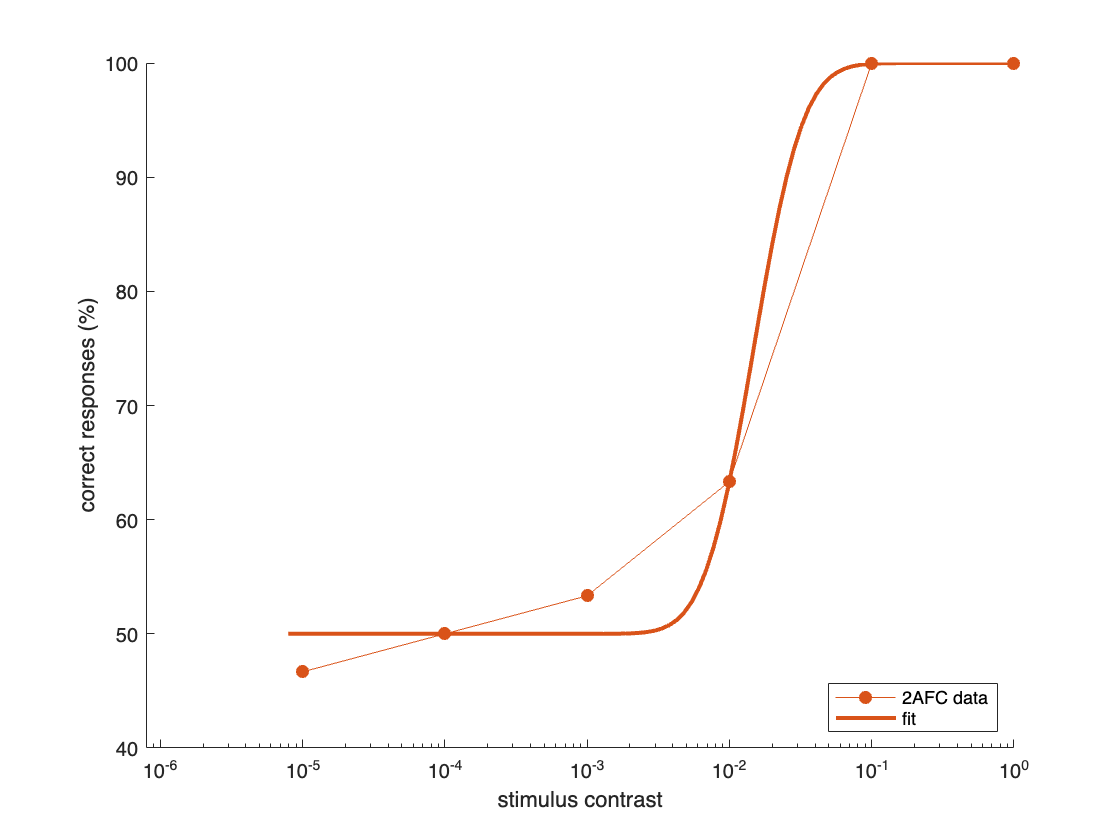

% plot forced choice results
figure; hold on;
plot(choice_results.contrast, choice_results.mean_response*100, ...
    'o-', 'Color',rgb_matlab(2,:), 'MarkerFaceColor',rgb_matlab(2,:))
set(gca,'XScale','log')
xlabel('stimulus contrast')
ylabel('correct responses (%)')

% add fitted curve
plot(psy_x_choice, psy_y_choice*100, '-', 'Color',rgb_matlab(2,:), 'LineWidth',2)
legend(["2AFC data","fit"], 'Location','southeast')
xlim(10.^[-6.1,0])

drawnow

**What do you think?** Did the optimization procedure do a good job fitting this data? Are adjustments needed this time around?

## Part C. Compare Forced Choice Experiments

You've now collected, analyzed, and fit data from a **simple forced choice** experiment and a **two-alternative forced choice (2AFC)** experiment. What are the similarities and differences between these two types of experiments? Do they produce similar data, or are there differences worth noting?

### Step 1. Compare performance

To make comparing and contrasting easier, let's plot the data from both experiments in the same figure.

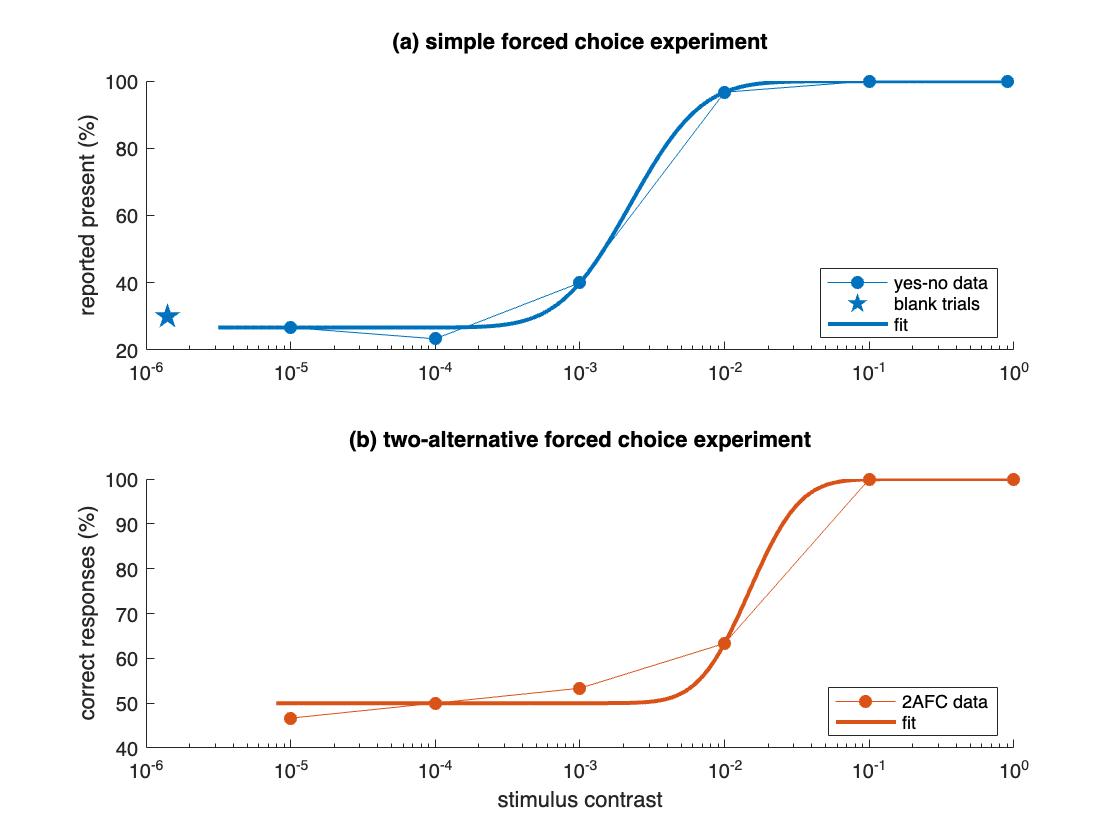

figure

% plot signal detection results
subplot(211); hold on;
plot(detection_results.contrast, detection_results.mean_response*100, ...
    'o-', 'Color',rgb_matlab(1,:), 'MarkerFaceColor',rgb_matlab(1,:))
plot(x_val_for_detection_blanks, detection_results.mean_response(1)*100, ...
    'pentagram', 'MarkerSize',12, 'Color',rgb_matlab(1,:), 'MarkerFaceColor',rgb_matlab(1,:))
plot(psy_x_detection, psy_y_detection*100, '-', 'Color',rgb_matlab(1,:), 'LineWidth',2)
set(gca,'XScale','log')
title(["(a) simple forced choice experiment",""])
ylabel('reported present (%)')
legend(["yes-no data", "blank trials", "fit"], 'Location','southeast')
xlim([10^-6,1])

% plot forced choice results
subplot(212); hold on;
plot(choice_results.contrast, choice_results.mean_response*100, ...
    'o-', 'Color',rgb_matlab(2,:), 'MarkerFaceColor',rgb_matlab(2,:))
plot(psy_x_choice, psy_y_choice*100, '-', 'Color',rgb_matlab(2,:), 'LineWidth',2)
set(gca,'XScale','log')
title(["(b) two-alternative forced choice experiment",""])
xlabel('stimulus contrast'); ylabel('correct responses (%)')
legend(["2AFC data", "fit"], 'Location','southeast')

drawnow

**What do you notice?** What's similar? What's different? Can you explain why those things are similar or different?

### Step 2. Compare psychometric curves

Let's zoom in and take a look at the parameter values for these two psychometric functions. (And we'll throw in the resnorm for fun.)

% organize values in a table
fit_results = table([psyfit_detection.'; resnorm_detection], ...
    [psyfit_choice.'; resnorm_choice], 'VariableNames',["yes-no", "2afc"], ...
    'RowNames',["mu", "sigma", "guess rate", "lapse rate", "resnorm"]);
fit_results.diff = table2array(fit_results(:,1)) - table2array(fit_results(:,2));
disp(fit_results)

                    yes-no         2afc          diff   
                  __________    __________    __________

    mu               -2.6517       -1.8293      -0.82239
    sigma            0.38314       0.27412       0.10901
    guess rate       0.26667       0.49999      -0.23333
    lapse rate    0.00044834    4.1296e-05    0.00040704
    resnorm        0.0022334     0.0022223    1.1019e-05



**What do you think? **How similar or different are each of the values? (The differences are shown in the 3rd column to make comparing easier; positive values indicate yes-no > 2AFC.)

Which parameter is the most similar? Which is the most different? Does that surprise you?

Was one fit much better or worse than the other? Does that line up with what you expected based on the plots?

### Step 3. Compare the participant experience

As a final step, think back to collecting data for these two experiments. **Considering the participant's experience of a task is a crucial part of experiment development**, so reflect on your experience with these two types of forced choice tasks. Did you prefer one over the other? What do you think are the pros and cons of both from the participant's perspective? Does anything come to mind that changes your thoughts about how the data compare?